# Implicit Deep Learning Tutorial on House price prediction dataset

clear all;
addpath([pwd,'/datasets/house_prices'])
[Y, Y_factor, U, U_test , feature_names] = process_house_prices_data();
submit = true;

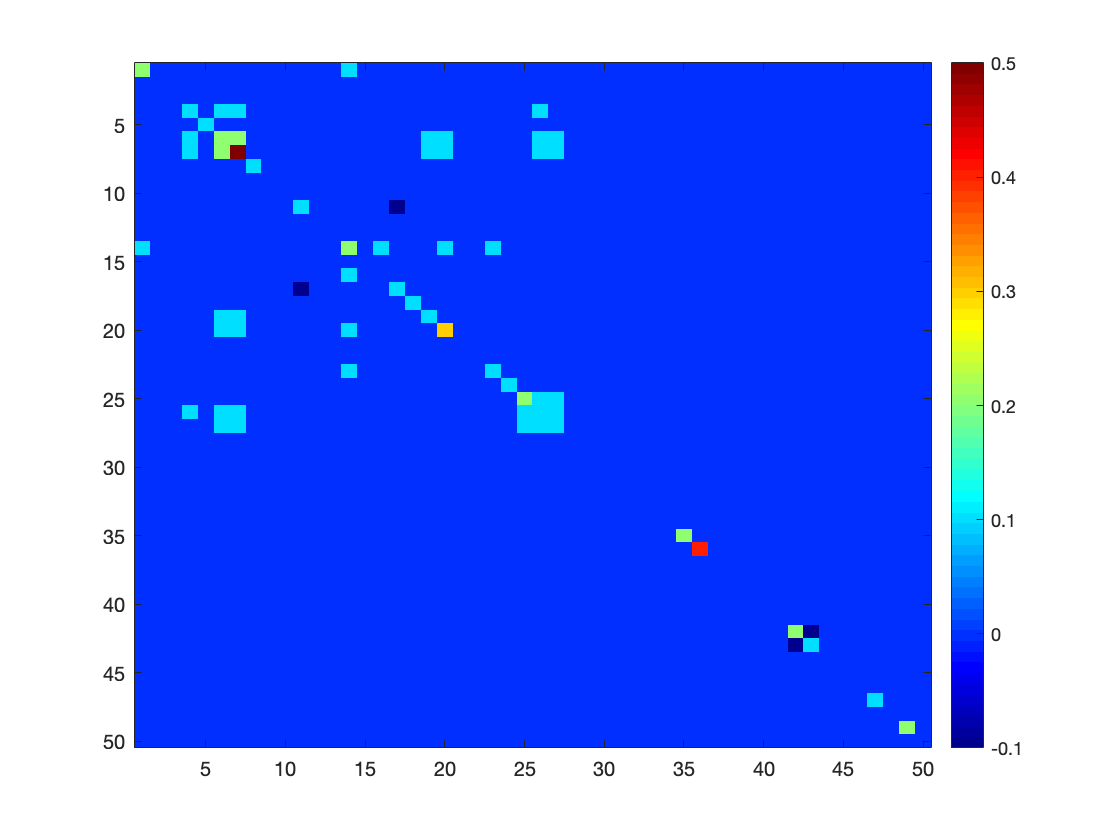

close all;
C = round(cov(U(1:50,:)'),1);
colormap('jet')
imagesc(C)
colorbar

[n,m] = size(U);
if submit == false
permutation = randperm(m);
% permute the data using this permutation vector
Y = Y(permutation); Y_train = Y(1:floor(3*m/4)); Y_validation = Y(ceil(3*m/4):m);
U = U(:,permutation); U_train = U(:,1:floor(3*m/4)); U_validation = U(:,ceil(3*m/4):m);
else
    Y_train = Y; Y_validation = Y; U_train = U; U_validation = U;
end
m_train = size(Y_train,2); m_validation = size(Y_validation,2);


$$y=\alpha^Tu+\beta$$


rho = 0.4;
gamma = 0.5;
Y_tmp=log(Y_train+1);
cvx_begin
variable a(n,1)
variable b(1)
minimize(norm(a'*U_train + b*ones(1,m_train)-Y_tmp,"fro") + rho*norm(a,1) + gamma*norm(a,2))
cvx_end

 
Calling SDPT3 4.0: 2392 variables, 623 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 623
 dim. of socp   var  = 2392,   num. of socp blk  = 312
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|5.5e+00|1.8e+01|2.3e+05| 0.000000e+00  0.000000e+00| 0:0:00| spchol  1  1 
 1|1.000|1.000|6.2e-05|3.8e-03|3.0e+04|-8.951755e-02 -3.007354e+04| 0:0:00| spchol  1  1 
 2|1.000|0.979|1.0e-07|4.7e-04|6.3e+02|-1.720898e-01 -6.314217e+02| 0:0:01| spchol  1  1 
 3|1.000|0.847|6.1e-08|1.0e-04|1.1e+02|-3.809233e+

Y_predicted = exp(a'*U_validation+b*ones(1,m_validation))-1;
score = 1/sqrt(m_validation)*norm(log(1+Y_predicted)-log(1+Y_validation));
disp(['estimated score: ', num2str(score)])

estimated score: 0.13063


n_feats=sum(round(a,2)~=0);
disp(['num of selected features: ', num2str(n_feats)])

num of selected features: 69


% reduce the dimension of features based on that
features = nonzeros((round(a,2)~=0)'.*(1:1:n))';

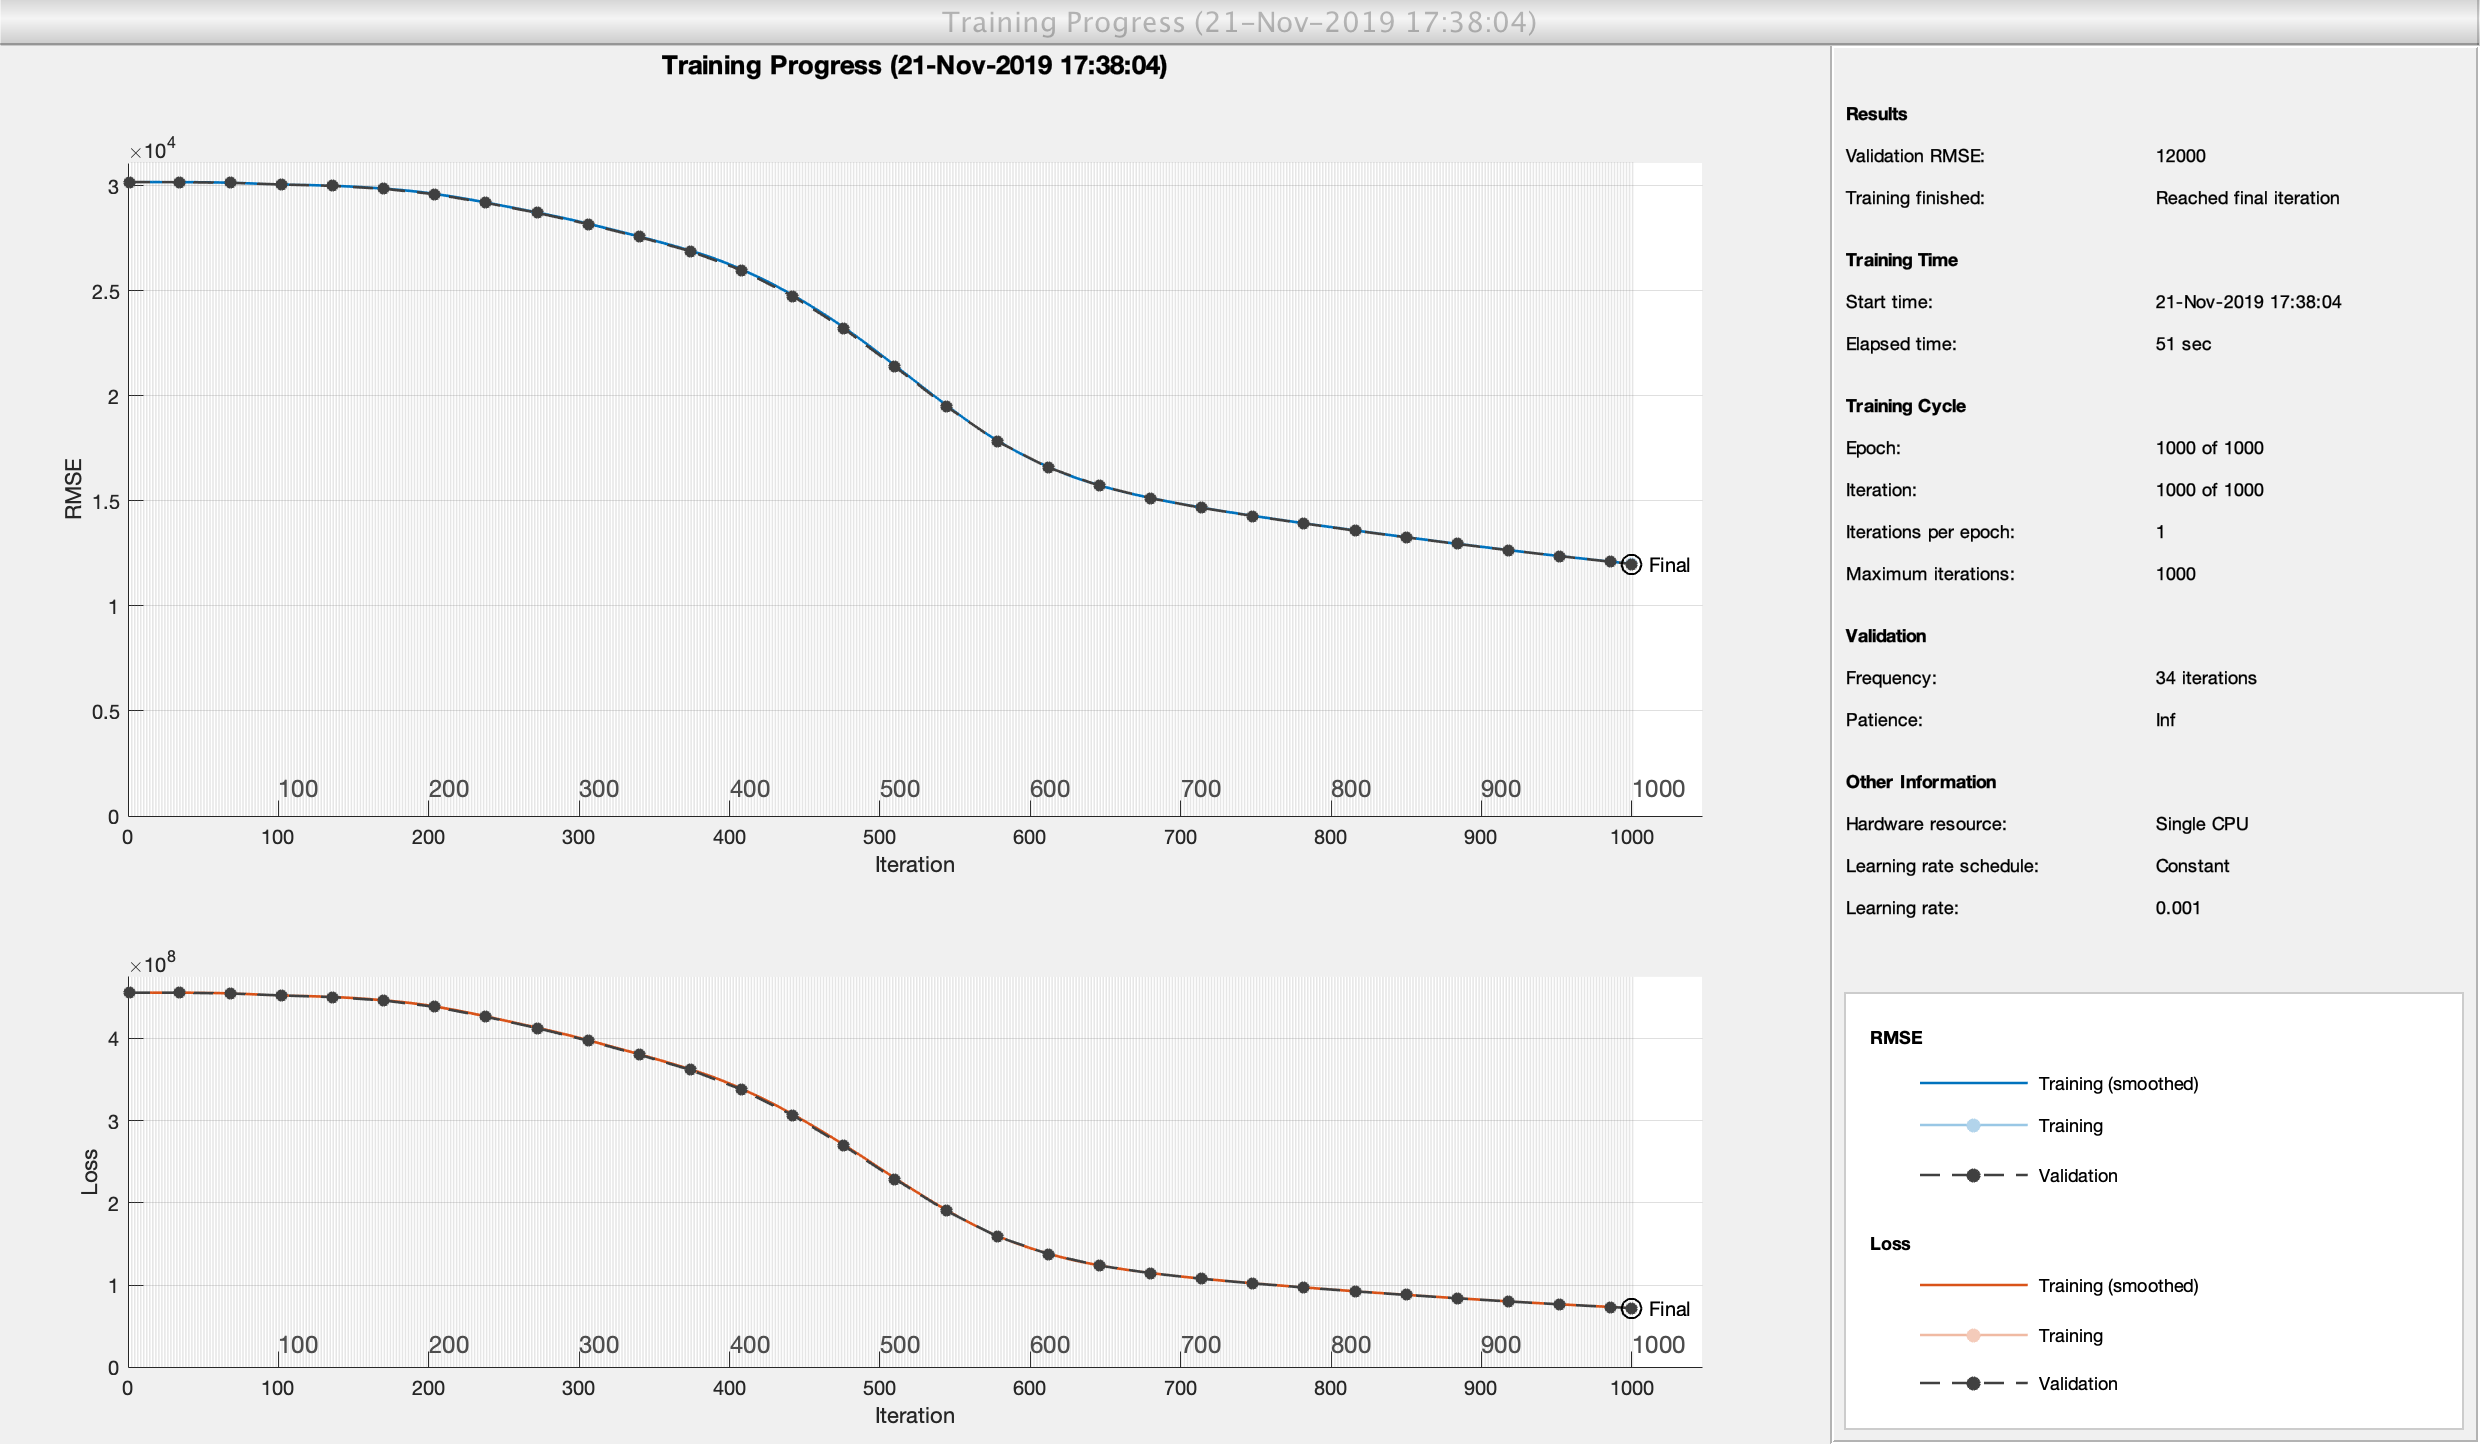

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |     30185.84 |     30185.82 |   4.5559e+08 |   4.5559e+08 |          0.0010 |
|      34 |          34 |       00:00:03 |     30183.58 |     30183.37 |   4.5552e+08 |   4.5552e+08 |          0.0010 |
|      50 |          50 |       00:00:04 |     30176.84 |              |   4.5532e+08 |              |          0.0010 |
|      68 |          68 |       00:00:05 |     30154.48 |     30152.59 |   4.5465e+08 |   4.5459e+08 |          0.0010 |
|     10

Error = Y - exp(a'*U + b*ones(1,m))+1;
if submit==false
    Error_train = Error(1:floor(3*m/4));
    Error_validation = Error(ceil(3*m/4):m);
else
    Error_train = Error;
    Error_validation =Error;
end

layers = [
    sequenceInputLayer(n_feats)
    fullyConnectedLayer(n_feats)
    reluLayer 
    fullyConnectedLayer(n_feats)
    reluLayer
    fullyConnectedLayer(n_feats)
    reluLayer
    fullyConnectedLayer(1)
    regressionLayer];
max_epochs= 5*10^2;
validationFrequency = ceil(max_epochs/30);
options = trainingOptions('adam','MaxEpochs',max_epochs,'MiniBatchSize',20,'InitialLearnRate',10^-3, ...
    'ValidationData',{U_validation(features,:),Error_validation}, 'ValidationFrequency',validationFrequency,'Plots','training-progress', 'L2Regularization', 10);
net = trainNetwork(U_train(features,:),Error_train,layers,options);

Y_predicted = exp(a'*U_validation + b*ones(1,m_validation)) + 1 + predict(net,U_validation(features,:));
score = 1/sqrt(m_validation)*norm(log(1+Y_predicted)-log(1+Y_validation));
disp(['estimated score: ', num2str(score)])

estimated score: 0.07781


if submit == true
    m_test = size(U_test,2);
    Y_test = exp(a'*U_test + b*ones(1,m_test)) + 1 +predict(net, U_test(features,:));
    Id=(1461:1:1461+m_test-1)';
    SalePrice=Y_test';
    T =table(Id,SalePrice);
    writetable(T,[pwd,'/datasets/submission.csv'])
end